# Bang-off-bang 调速策略

Author： Tenplus

Create-time：2022-03-19

Update-time：2022-06-04 V4.0

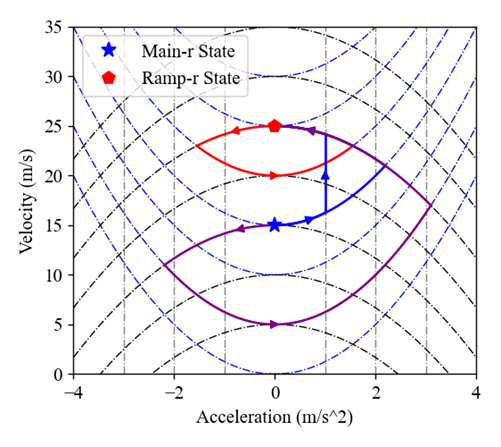

从初状态$\;t_0 ,\;\left\lbrack p_0 ,v_0 ,a_0 \right\rbrack \;$调整至 $t_f ,\left\lbrack p_f ,v_f ,a_f \right\rbrack \;$，过程状态在上图曲线中切换，最大切换次数为 3-1=2 次。

- 一次切换，两阶段（$j_{\max } \to j_{\min }$）得到极值点

- 两次切换，三阶段（$j_{\min } \to j_{\max } \to j_{\min }$）减速后调整，为了达到某个给定的 pf

- 两次切换，三阶段（$j_{\max } \to 0\to j_{\min }$）对于匝道车辆，直接加速的极值点

## 一次切换，两阶段 $j_{\max } \to j_{\min }$

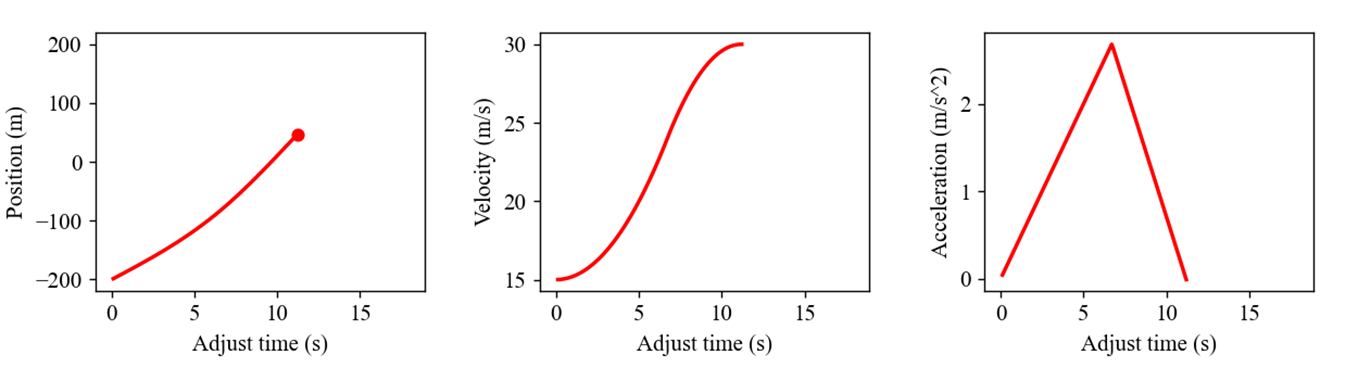

适用范围：主道和匝道的 pole 点，无约束下，tf 和 pf 的最小值

syms t t1 t2 a0 v0 p0 v_M j_min j_max

% 第一阶段，OA段
a1 = j_max * t + a0;
v1 = 1/2 * j_max * t^2 + a0 * t + v0;
p1 = 1/6 * j_max * t^3 + 1/2 * a0 * t^2 + v0 * t + p0;

% A点坐标
A_a = subs(a1, t, t1);
A_v = subs(v1, t, t1);
A_p = subs(p1, t, t1);

% 第二阶段，AB段
a2 = j_min * (t-t1) + j_max * t1 + a0;
v2 = 1/2 * j_min * (t-t1)^2 + (j_max*t1 + a0) * t - 1/2 * j_max * t1^2 + v0;
p2 = 1/6 * j_min * (t-t1)^3 + 1/2 * (j_max*t1 + a0) * t^2 + (- 1/2 * j_max * t1^2 + v0) * t + ...
     (j_max*t1^3)/6 + p0;

% Check a2 v2 p2
checker_a2 = subs(a2, t, t1) - A_a;
checker_v2 = expand(subs(v2, t, t1) - A_v);
checker_p2 = expand(subs(p2, t, t1) - A_p);

% B点
B_a = subs(a2, t, t1+t2)

$$B\_a = a_{0}+j_{\min}\,t_{2}+j_{\max}\,t_{1}$$

B_v = subs(v2, t, t1+t2)

$$B\_v = v_{0}+\frac{j_{\min}\,{t_{2}}^{2}}{2}-\frac{j_{\max}\,{t_{1}}^{2}}{2}+\left(t_{1}+t_{2}\right)\,\left(a_{0}+j_{\max}\,t_{1}\right)$$

B_p = subs(p2, t, t1+t2)

$$B\_p = p_{0}+\left(t_{1}+t_{2}\right)\,\left(v_{0}-\frac{j_{\max}\,{t_{1}}^{2}}{2}\right)+{\left(t_{1}+t_{2}\right)}^{2}\,\left(\frac{a_{0}}{2}+\frac{j_{\max}\,t_{1}}{2}\right)+\frac{j_{\min}\,{t_{2}}^{3}}{6}+\frac{j_{\max}\,{t_{1}}^{3}}{6}$$


% 在 B点联立等式，可以求解 t1、t2、pf
% B_a = 0, B_v = v_M

## 一次切换，两阶段 $0\to j_{\min }$

syms t t1 t2 a0 v0 p0 v_M j_min j_max

% 第一阶段，OA段
a1 = a0;
v1 = a0 * t + v0;
p1 = 1/2 * a0 * t^2 + v0 * t + p0;

% A点坐标
A_a = subs(a1, t, t1);
A_v = subs(v1, t, t1);
A_p = subs(p1, t, t1);

% 第二阶段，AB段
a2 = j_min * (t-t1) + a0;
v2 = 1/2 * j_min * (t-t1)^2 + a0 * t + v0;
p2 = 1/6 * j_min * (t-t1)^3 + 1/2 * a0 * t^2 + v0 * t + p0;

% Check a2 v2 p2
checker_a2 = subs(a2, t, t1) - A_a;
checker_v2 = expand(subs(v2, t, t1) - A_v);
checker_p2 = expand(subs(p2, t, t1) - A_p);

% B点
B_a = subs(a2, t, t1+t2)

$$B\_a = a_{0}+j_{\min}\,t_{2}$$

B_v = subs(v2, t, t1+t2)

$$B\_v = v_{0}+a_{0}\,\left(t_{1}+t_{2}\right)+\frac{j_{\min}\,{t_{2}}^{2}}{2}$$

B_p = subs(p2, t, t1+t2)

$$B\_p = p_{0}+v_{0}\,\left(t_{1}+t_{2}\right)+\frac{a_{0}\,{\left(t_{1}+t_{2}\right)}^{2}}{2}+\frac{j_{\min}\,{t_{2}}^{3}}{6}$$


% 在 B点联立等式，可以求解 t1、t2、pf
% B_a = 0, B_v = v_M


## 两次切换，三阶段 $j_{\max } \to 0\to j_{\min }$

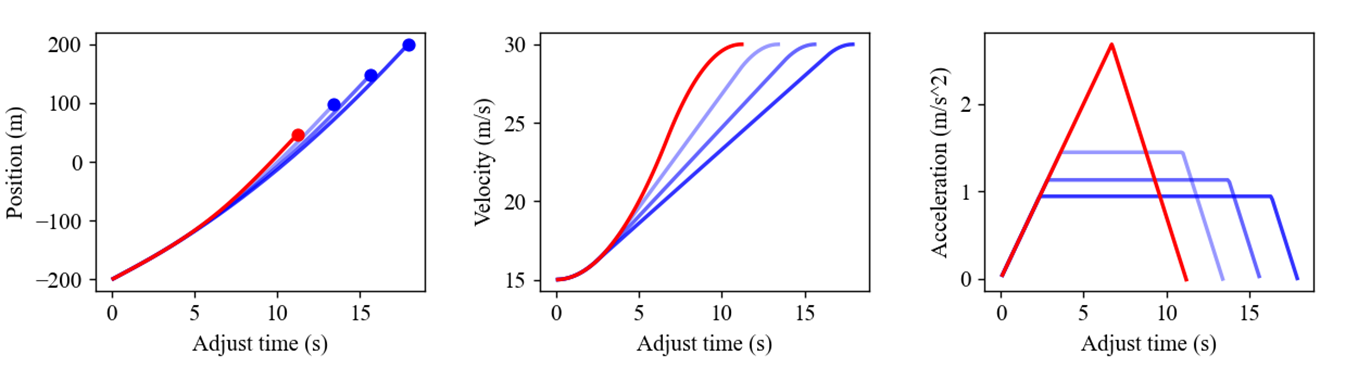

使用范围：匝道车辆以时间最小方式加速，达到末状态 pf，且用时最短。

syms t t1 t2 t3 a0 v0 p0 v_M j_min j_max

% 第一阶段，OA段
a1 = j_max * t + a0;
v1 = 1/2 * j_max * t^2 + a0 * t + v0;
p1 = 1/6 * j_max * t^3 + 1/2 * a0 * t^2 + v0 * t + p0;

% A点坐标
A_a = subs(a1, t, t1);
A_v = subs(v1, t, t1);
A_p = subs(p1, t, t1);

% 第二阶段，AB段
a2 = j_max * t1 + a0;
v2 = (j_max * t1 + a0) * t + (-1/2*j_max*t1^2 + v0);
p2 = 1/2 * (j_max * t1 + a0) * t^2 + (-1/2*j_max*t1^2 + v0)*t + (1/6 * j_max * t1^3 + p0);

% Check a2 v2 p2
checker_a2 = subs(a2, t, t1) - A_a;
checker_v2 = expand(subs(v2, t, t1) - A_v);
checker_p2 = expand(subs(p2, t, t1) - A_p);

% B点
B_a = subs(a2, t, t1+t2);
B_v = subs(v2, t, t1+t2);
B_p = expand(subs(p2, t, t1+t2));
 
% 第三阶段，BC段
a3 = j_min * (t-t1-t2) + (j_max*t1 + a0);
v3 = 1/2*j_min * (t-t1-t2)^2 + (j_max*t1 + a0)*t + (-1/2*j_max*t1^2 + v0);
p3 = 1/6*j_min * (t-t1-t2)^3 + 1/2*(j_max*t1 + a0)*t^2 + (-1/2*j_max*t1^2 + v0)*t + (1/6 * j_max * t1^3 + p0);

% Checker a3 v3 p3
checker_a3 = expand(subs(a3, t, t1+t2) - B_a);
checker_v3 = expand(subs(v3, t, t1+t2) - B_v);
checker_p3 = expand(subs(p3, t, t1+t2) - B_p);

% % C点坐标
C_a = subs(a3, t, t1+t2+t3)

$$C\_a = a_{0}+j_{\min}\,t_{3}+j_{\max}\,t_{1}$$

C_v = subs(v3, t, t1+t2+t3)

$$C\_v = v_{0}+\left(a_{0}+j_{\max}\,t_{1}\right)\,\left(t_{1}+t_{2}+t_{3}\right)+\frac{j_{\min}\,{t_{3}}^{2}}{2}-\frac{j_{\max}\,{t_{1}}^{2}}{2}$$

C_p = subs(p3, t, t1+t2+t3)

$$C\_p = p_{0}+\left(v_{0}-\frac{j_{\max}\,{t_{1}}^{2}}{2}\right)\,\left(t_{1}+t_{2}+t_{3}\right)+\frac{j_{\min}\,{t_{3}}^{3}}{6}+\frac{j_{\max}\,{t_{1}}^{3}}{6}+\left(\frac{a_{0}}{2}+\frac{j_{\max}\,t_{1}}{2}\right)\,{\left(t_{1}+t_{2}+t_{3}\right)}^{2}$$


% 在 C点联立等式，可以求解 t1、t2、t3
% C_a = 0, C_v = v_M, C_p = pf

## 两次切换，三阶段 $j_{\min } \to j_{\max } \to j_{\min }$

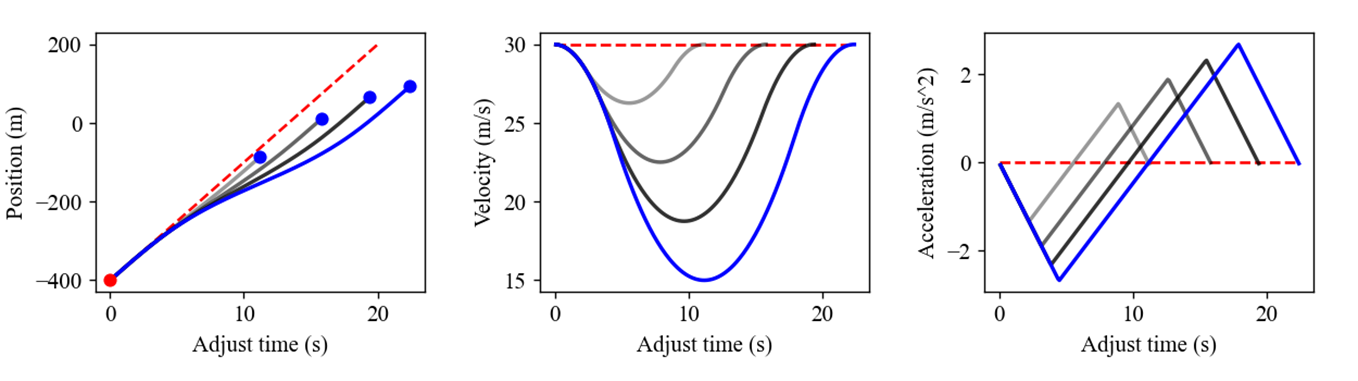

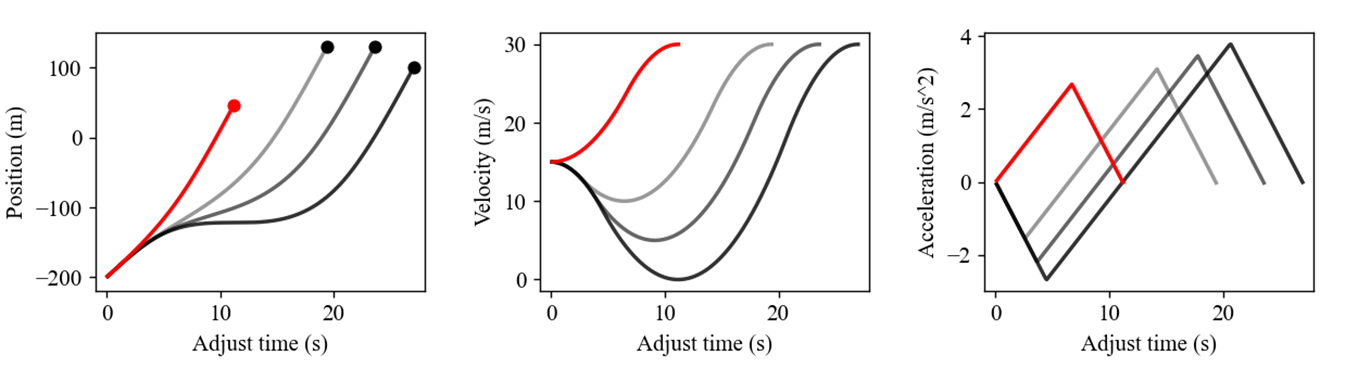

适用范围：主道车辆减速拉开间距，匝道车辆减速以等待

多种模式：

- 当匝道速度调整范围受限时，弧形只有左半边可行：输入参数：pf，输出：t1, t2, t3

- 当 tf < tf_stop 时：输入 tf，输出 t1、t2、t3、pf

- 当 给定 v_min 时，求得一个极限值，输入 v_min，输出 t1 t2 t3 pf

syms t t1 t2 t3 a0 v0 p0 v_M j_min j_max

% 第一阶段，OA段
a1 = j_min * t + a0;
v1 = 1/2 * j_min * t^2 + a0 * t + v0;
p1 = 1/6 * j_min * t^3 + 1/2 * a0 * t^2 + v0 * t + p0;

% A点坐标
A_a = subs(a1, t, t1);
A_v = subs(v1, t, t1);
A_p = subs(p1, t, t1);

% 第二阶段，AB段
a2 = j_max * (t-t1) + j_min * t1 + a0

$$a2 = a_{0}+j_{\min}\,t_{1}+j_{\max}\,\left(t-t_{1}\right)$$

v2 = 1/2 * j_max * (t-t1)^2 + (j_min*t1 + a0) * t - 1/2 * j_min * t1^2 + v0

$$v2 = v_{0}-\frac{j_{\min}\,{t_{1}}^{2}}{2}+\frac{j_{\max}\,{\left(t-t_{1}\right)}^{2}}{2}+t\,\left(a_{0}+j_{\min}\,t_{1}\right)$$

p2 = 1/6 * j_max * (t-t1)^3 + 1/2 * (j_min*t1 + a0) * t^2 + (- 1/2 * j_min * t1^2 + v0) * t + ...
     (j_min*t1^3)/6 + p0;

% Check a2 v2 p2
% checker_a2 = subs(a2, t, t1) - A_a
% checker_v2 = expand(subs(v2, t, t1) - A_v);
% checker_p2 = expand(subs(p2, t, t1) - A_p);
 
% B点
B_a = subs(a2, t, t1+t2)

$$B\_a = a_{0}+j_{\min}\,t_{1}+j_{\max}\,t_{2}$$

B_v = expand(subs(v2, t, t1+t2))

$$B\_v = \frac{j_{\min}\,{t_{1}}^{2}}{2}+j_{\min}\,t_{1}\,t_{2}+a_{0}\,t_{1}+\frac{j_{\max}\,{t_{2}}^{2}}{2}+a_{0}\,t_{2}+v_{0}$$

B_p = expand(subs(p2, t, t1+t2));

% 速度最小的点
v_min = expand(subs(v2, t, t1-(j_min*t1+a0)/j_max))

$$v\_min = v_{0}+a_{0}\,t_{1}+\frac{j_{\min}\,{t_{1}}^{2}}{2}-\frac{{a_{0}}^{2}}{2\,j_{\max}}-\frac{{j_{\min}}^{2}\,{t_{1}}^{2}}{2\,j_{\max}}-\frac{a_{0}\,j_{\min}\,t_{1}}{j_{\max}}$$


% 第三阶段，BC段
a3 = j_min * (t-t1-t2) + (j_min*t1 + j_max*t2 + a0);
v3 = 1/2 * j_min * (t-t1-t2)^2 + (j_min*t1 + j_max*t2 + a0) * t + (v0 - j_min* 1/2 * t1^2 - j_max*t1*t2 - j_max*1/2*t2^2);
p3 = 1/6 * j_min * (t-t1-t2)^3 + 1/2*(j_min*t1 + j_max*t2 + a0) * t^2 + (v0 - j_min* 1/2 * t1^2 - j_max*t1*t2 - j_max*1/2*t2^2) *t + ...
    + (1/6*j_min*t1^3 + 1/2*j_max*t1^2*t2 + 1/2*j_max*t1*t2^2 + 1/6*j_max*t2^3 + p0);

% Checker a3 v3 p3
checker_a3 = expand(subs(a3, t, t1+t2) - B_a);
checker_v3 = expand(subs(v3, t, t1+t2) - B_v);
checker_p3 = expand(subs(p3, t, t1+t2) - B_p);

% C点坐标
C_a = subs(a3, t, t1+t2+t3)

$$C\_a = a_{0}+j_{\min}\,t_{1}+j_{\min}\,t_{3}+j_{\max}\,t_{2}$$

C_v = subs(v3, t, t1+t2+t3)

$$C\_v = v_{0}+\left(a_{0}+j_{\min}\,t_{1}+j_{\max}\,t_{2}\right)\,\left(t_{1}+t_{2}+t_{3}\right)-\frac{j_{\min}\,{t_{1}}^{2}}{2}+\frac{j_{\min}\,{t_{3}}^{2}}{2}-\frac{j_{\max}\,{t_{2}}^{2}}{2}-j_{\max}\,t_{1}\,t_{2}$$

C_p = subs(p3, t, t1+t2+t3)

$$C\_p = p_{0}+\left(\frac{a_{0}}{2}+\frac{j_{\min}\,t_{1}}{2}+\frac{j_{\max}\,t_{2}}{2}\right)\,{\left(t_{1}+t_{2}+t_{3}\right)}^{2}-\left(t_{1}+t_{2}+t_{3}\right)\,\left(\frac{j_{\min}\,{t_{1}}^{2}}{2}+j_{\max}\,t_{1}\,t_{2}+\frac{j_{\max}\,{t_{2}}^{2}}{2}-v_{0}\right)+\frac{j_{\min}\,{t_{1}}^{3}}{6}+\frac{j_{\min}\,{t_{3}}^{3}}{6}+\frac{j_{\max}\,{t_{2}}^{3}}{6}+\frac{j_{\max}\,t_{1}\,{t_{2}}^{2}}{2}+\frac{j_{\max}\,{t_{1}}^{2}\,t_{2}}{2}$$


% 共可以列写最多四个等式，包括 v_min 处的取值


## 四次切换，五阶段 $j_{\min } \to j_{\max } \to 0\to j_{\max } \to j_{\min }$

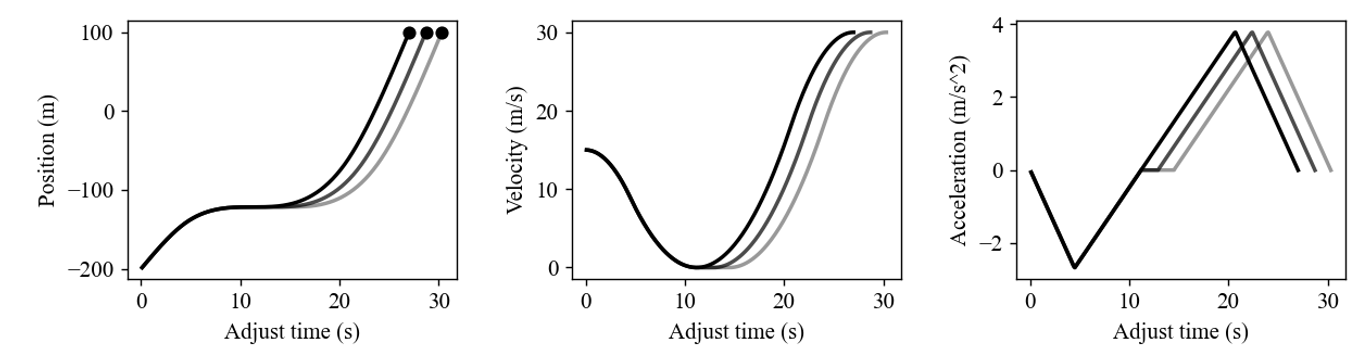

适用范围：匝道车辆减速出现停车的情况

原来的 t1、t2、t3 仍然保持适用，t2 被分割为三段：t2_left、t2_stop、t2_right

开始停车的点 B点，用上面的公式，在时间的处理上考虑到这个问题

- t2_left = -(j_min*t1+a0)/j_max)

- t2_stop = tf - (t1-t2-t3)

- t2_right = t2 - t2_1

syms t t1 t2 t3 a0 v0 p0 v_M j_min j_max t2_left t2_stop t2_right p_stop

% 第一阶段，OA段  
a1 = j_min * t + a0;
v1 = 1/2 * j_min * t^2 + a0 * t + v0;
p1 = 1/6 * j_min * t^3 + 1/2 * a0 * t^2 + v0 * t + p0;

% A点坐标; t1
A_a = subs(a1, t, t1);
A_v = subs(v1, t, t1);
A_p = subs(p1, t, t1);

% 第二阶段，AB段; t1+t2_left
a2 = j_max * (t-t1) + j_min * t1 + a0;
v2 = 1/2 * j_max * (t-t1)^2 + (j_min*t1 + a0) * t - 1/2 * j_min * t1^2 + v0;
p2 = 1/6 * j_max * (t-t1)^3 + 1/2 * (j_min*t1 + a0) * t^2 + (- 1/2 * j_min * t1^2 + v0) * t + ...
     (j_min*t1^3)/6 + p0;

% B点坐标，
B_a = 0;
B_v = 0;
B_p = expand(subs(p2, t, t1+t2_left))

$$B\_p = \frac{j_{\min}\,{t_{1}}^{3}}{6}+\frac{j_{\min}\,{t_{1}}^{2}\,t_{2,\mathrm{left}}}{2}+\frac{a_{0}\,{t_{1}}^{2}}{2}+\frac{j_{\min}\,t_{1}\,{t_{2,\mathrm{left}}}^{2}}{2}+a_{0}\,t_{1}\,t_{2,\mathrm{left}}+v_{0}\,t_{1}+\frac{j_{\max}\,{t_{2,\mathrm{left}}}^{3}}{6}+\frac{a_{0}\,{t_{2,\mathrm{left}}}^{2}}{2}+v_{0}\,t_{2,\mathrm{left}}+p_{0}$$

% 这里需要求出 B_p 的值，对于是后阶段的起点

% 第三阶段，BC段；t1+t2_left+t2_stop
a3 = 0;
v3 = 0;
p3 = p_stop;

% 第四阶段，CD段；t1+t2
a4 = j_max * (t-t1-t2_left-t2_stop);
v4 = 1/2 * j_max * (t-t1-t2_left-t2_stop)^2;
p4 = 1/6 * j_max * (t-t1-t2_left-t2_stop)^3 + p_stop;

% D 点坐标
D_a = expand(subs(a4, t, t1+t2_left+t2_stop+t2_right));
D_v = expand(subs(v4, t, t1+t2_left+t2_stop+t2_right));
D_p = expand(subs(p4, t, t1+t2_left+t2_stop+t2_right));

% 第五阶段，DE段：t1 + t2 + t3
a5 = j_min * (t-t1-t2_left-t2_stop-t2_right) + j_max * t2_right;
v5 = 1/2 * j_min * (t-t1-t2_left-t2_stop-t2_right)^2 + j_max * t2_right * t - j_max * (t2_right^2/2 + t1*t2_right + t2_left*t2_right + t2_stop*t2_right);
p5 = 1/6 * j_min * (t-t1-t2_left-t2_stop-t2_right)^3 + 1/2 * j_max * t2_right * t^2 ...
    - j_max * (t2_right^2/2 + t1*t2_right + t2_left*t2_right + t2_stop*t2_right) * t ...
    + j_max * t2_right * (t1^2/2 + t1*t2_left + t2_left^2/2 + t2_stop^2/2+t1*t2_stop+t2_left*t2_stop) ...
    + j_max * t2_right^2 / 2 * (t1 + t2_left + t2_stop) ...
    + j_max * t2_right^3 / 6 + p_stop

$$p5 = p_{\mathrm{stop}}-\frac{j_{\min}\,{\left(t_{1}-t+t_{2,\mathrm{left}}+t_{2,\mathrm{stop}}+t_{2,\mathrm{right}}\right)}^{3}}{6}+\frac{j_{\max}\,{t_{2,\mathrm{right}}}^{3}}{6}+j_{\max}\,t_{2,\mathrm{right}}\,\left(\frac{{t_{1}}^{2}}{2}+t_{1}\,t_{2,\mathrm{left}}+t_{1}\,t_{2,\mathrm{stop}}+\frac{{t_{2,\mathrm{left}}}^{2}}{2}+t_{2,\mathrm{left}}\,t_{2,\mathrm{stop}}+\frac{{t_{2,\mathrm{stop}}}^{2}}{2}\right)+\frac{j_{\max}\,t^{2}\,t_{2,\mathrm{right}}}{2}+\frac{j_{\max}\,{t_{2,\mathrm{right}}}^{2}\,\left(t_{1}+t_{2,\mathrm{left}}+t_{2,\mathrm{stop}}\right)}{2}-j_{\max}\,t\,\left(t_{1}\,t_{2,\mathrm{right}}+t_{2,\mathrm{left}}\,t_{2,\mathrm{right}}+t_{2,\mathrm{stop}}\,t_{2,\mathrm{right}}+\frac{{t_{2,\mathrm{right}}}^{2}}{2}\right)$$


checker_v5 = expand(subs(v5, t, t1+t2_left+t2_stop+t2_right) - D_v);
checker_p5 = expand(subs(p5, t, t1+t2_left+t2_stop+t2_right) - D_p)

$$checker\_p5 = 0$$

% 公式已经 check，没毛病

## 四次切换，五阶段 $j_{\min } \to j_{\max } \to 0\to j_{\max } \to j_{\min }$ （速度不到0，保持在最小速度 v_min）

五个阶段，A：t1（j_min）、B：t2（j_max）、C：t3（j=0）、D: t4（j_max）、E：t5（j_min）、pf，写方程组

syms t t1 t2 t3 t4 t5 a0 v0 p0 v_min v_M j_min j_max

% 第一阶段，OA段
a1 = j_min * t + a0;
v1 = 1/2 * j_min * t^2 + a0 * t + v0;
p1 = 1/6 * j_min * t^3 + 1/2 * a0 * t^2 + v0 * t + p0;

% A点坐标
A_a = subs(a1, t, t1);
A_v = subs(v1, t, t1);
A_p = subs(p1, t, t1);

% 第二阶段，AB段
a2 = j_max * (t-t1) + j_min * t1 + a0;
v2 = 1/2 * j_max * (t-t1)^2 + (j_min*t1 + a0) * t - 1/2 * j_min * t1^2 + v0;
p2 = 1/6 * j_max * (t-t1)^3 + 1/2 * (j_min*t1 + a0) * t^2 + (- 1/2 * j_min * t1^2 + v0) * t + ...
     (j_min*t1^3)/6 + p0;

% Check a2 v2 p2
% checker_a2 = subs(a2, t, t1) - A_a
% checker_v2 = expand(subs(v2, t, t1) - A_v);
% checker_p2 = expand(subs(p2, t, t1) - A_p);
 
% B点
B_a = subs(a2, t, t1+t2);
B_v = expand(subs(v2, t, t1+t2));
B_p = expand(subs(p2, t, t1+t2))

$$B\_p = \frac{j_{\min}\,{t_{1}}^{3}}{6}+\frac{j_{\min}\,{t_{1}}^{2}\,t_{2}}{2}+\frac{a_{0}\,{t_{1}}^{2}}{2}+\frac{j_{\min}\,t_{1}\,{t_{2}}^{2}}{2}+a_{0}\,t_{1}\,t_{2}+v_{0}\,t_{1}+\frac{j_{\max}\,{t_{2}}^{3}}{6}+\frac{a_{0}\,{t_{2}}^{2}}{2}+v_{0}\,t_{2}+p_{0}$$



% 第三阶段，匀速，v_min
syms B_p_
a3 = 0;
v3 = v_min;
p3 = B_p_ + (t-t1-t2) * v_min;

% C点
C_a = 0;
C_v = v_min;
C_p = B_p_ + t3 * v_min

$$C\_p = B_{\mathrm{p\_}}+t_{3}\,v_{\min}$$


% 第四阶段，j_max
syms t123 C_p_
a4 = j_max * (t-t123);
v4 = 1/2 * j_max * (t-t123)^2 + v_min;
p4 = 1/6 * j_max * (t-t123)^3 + v_min * t + C_p_ - t123 * v_min

$$p4 = C_{\mathrm{p\_}}+t\,v_{\min}-t_{123}\,v_{\min}+\frac{j_{\max}\,{\left(t-t_{123}\right)}^{3}}{6}$$


% D点
D_a = subs(a4, t, t123+t4);
D_v = expand(subs(v4, t, t123+t4));
D_p = expand(subs(p4, t, t123+t4));

% % 第五阶段，j_min
a5 = j_min * (t-t123-t4) + j_max * t4;
v5 = 1/2 * j_min * (t-t123-t4)^2 + j_max * t4 * t - 1/2 * j_max * t4^2 - j_max * t123 * t4 + v_min;
p5 = 1/6 * j_min * (t-t123-t4)^3 + 1/2 * j_max * t4 * t^2 + (v_min - 1/2 * j_max * t4^2 - j_max * t123 * t4) * t + j_max * (1/6 * t4^3 + 1/2*t4^2*t123+1/2*t4*t123^2) + C_p_ - t123 * v_min;

% % Check a5 v5 p5
% checker_a5 = subs(a5, t, t123+t4) - D_a;
% checker_v5 = - expand(subs(v5, t, t123+t4) - D_v);
% checker_p5 = - expand(subs(p5, t, t123+t4) - D_p);
% 
% E点位移；
E_p = expand(subs(p5, t, t123+t4+t5))

$$E\_p = \frac{j_{\max}\,{t_{4}}^{3}}{6}+\frac{j_{\max}\,{t_{4}}^{2}\,t_{5}}{2}+\frac{j_{\max}\,t_{4}\,{t_{5}}^{2}}{2}+v_{\min}\,t_{4}+\frac{j_{\min}\,{t_{5}}^{3}}{6}+v_{\min}\,t_{5}+C_{\mathrm{p\_}}$$